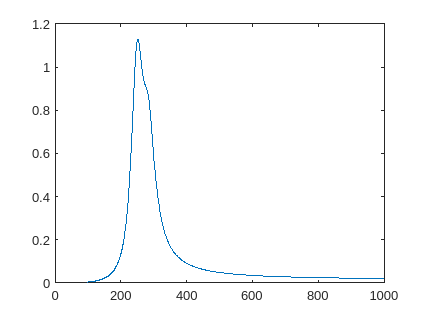

%project 

% 1. 
% Kramer-konig relation 
A=importdata('extinctionSpectrum.txt');
plot(A.data(:,1), A.data(:,2))

%PAIN...




% 2. 
% %Gauss's Law 

a = -pi : pi/2 : pi;                                % Define Corners
ph = pi/4;                                          % Define Angular Orientation (‘Phase’)
x = [cos(a+ph); cos(a+ph)]/cos(ph);
y = [sin(a+ph); sin(a+ph)]/sin(ph);
z = [-ones(size(a)); ones(size(a))];
figure
surf(x, y, z, 'FaceColor','w')                      % Plot Cube
hold on
patch(x', y', z', 'w')                              % Make Cube Appear Solid
hold off
axis([ -1  1    -1  1    -1  1]*1.5)
grid on

hold on
[X,Y,Z] = sphere(10);
[U,V,W] = surfnorm(X,Y,Z);
quiver3(X,Y,Z,U,V,W,0)
axis equal
hold off

% 3. 
% %moment of inertia 
% %off diagonal should be zero 
% 
% x=linspace(-0.5,0.5,11); 
% y=x; 
% 
% 
% [X1,Y1]=meshgrid(x,y); 
% 
% Z=zeros(size(X1)); 
% 
% % s1=surf(X1,Y1,Z);
% axis(1*[-1 1 -1 1 -1 1 -1 1])

a = -pi : pi/2 : pi;                                % Define Corners
ph = pi/4;                                          % Define Angular Orientation (‘Phase’)
x = [cos(a+ph); cos(a+ph)]/cos(ph);
y = [sin(a+ph); sin(a+ph)]/sin(ph);
z = [-ones(size(a)); ones(size(a))];
figure
s1 = surf(x, y, z, 'FaceColor','g')                      % Plot Cube

s1 =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: [0 1 0]
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [2×5 double]
           YData: [2×5 double]
           ZData: [2×5 double]
           CData: [2×5 double]

  Show all properties


hold on
s2 = patch(x', y', z', 'g')                              % Make Cube Appear Solid

s2 =   Patch with properties:

    FaceColor: [0 1 0]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [2×5 double]
     Vertices: [10×3 double]

  Show all properties


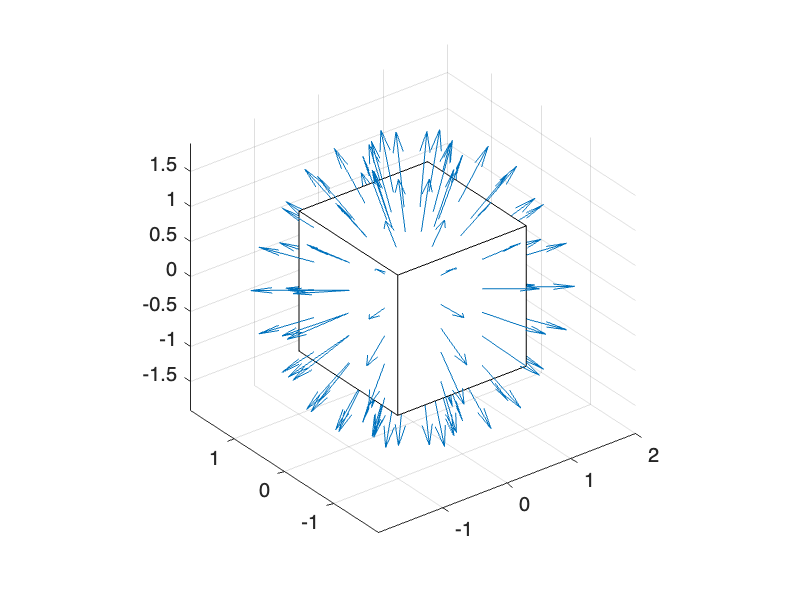

hold off
axis([ -1  1    -1  1    -1  1]*3)
grid on



direc=[0 0 1];
orig=2*[0 0 0];

xline=orig(1)+direc(1)*[4 -4];
yline=orig(2)+direc(2)*[4 -4];
zline=orig(3)+direc(3)*[4 -4];

hold on
p1=plot3(xline,yline,zline,'r','LineWidth',3);
hold off




theta=10;
for i=1:720/theta
    pause(0.1)
rotate(s1,direc,theta,orig)
rotate(s2,direc,theta,orig)
end 

%create a box instead of surface

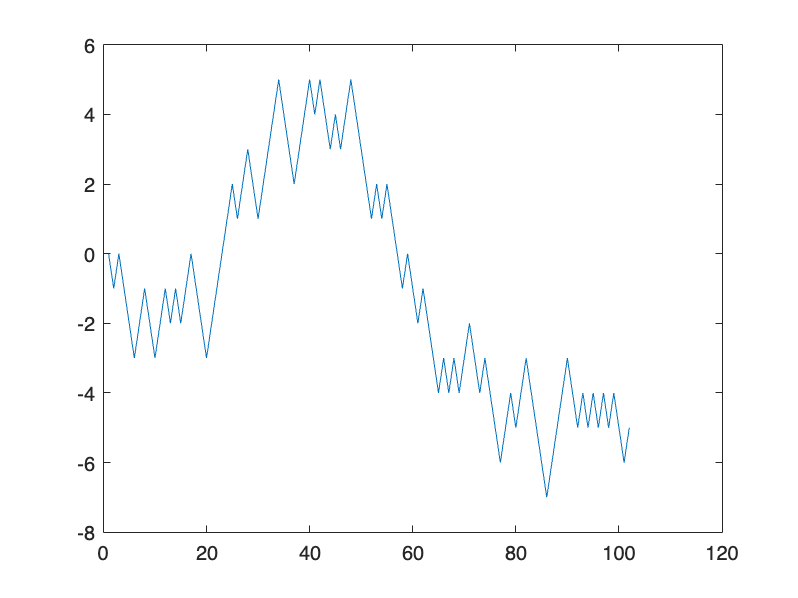

% 4. 
% %random walks 
% %1D, 2D,
% 

%1D
N0=0;
n=100;
dn=1;
b=(0:dn:n)';
%mark the probability for taking +1 and -1 as 50% 
N=zeros(size(b)); 

for i=1:size(N)
    if rand<0.5 
       N(i+1)=N(i)+1;
    else 
        N(i+1)=N(i)-1;
    end 

end
plot(N)

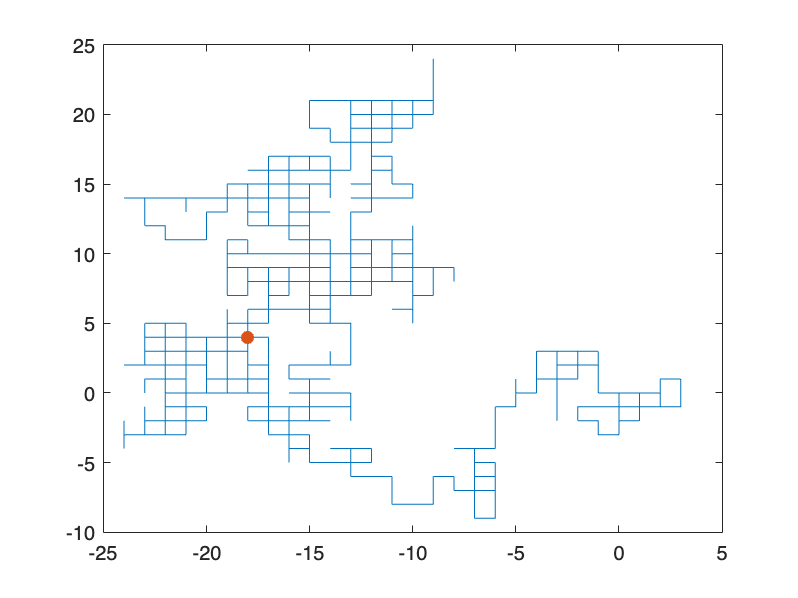




%2D
N=1000;

x=NaN([N,1]);
y=NaN([N,1]);
x(1)=0; 
y(1)=0;

p1=plot (x,y,'-');
hold on
p2=plot(x(1),y(1),'o');
p2.MarkerFaceColor=p2.Color;
hold off 

%for each step 
for i=1 : N 
    pause(10/N);
    step=rand; 
    if step< 1/4 
        x(i+1)=x(i)+1;
        y(i+1)=y(i);
    elseif step< 2/4 
        x(i+1)=x(i)-1;
        y(i+1)=y(i);
    elseif step< 3/4 
        x(i+1)=x(i);
        y(i+1)=y(i)+1;
    else 
         x(i+1)=x(i);
        y(i+1)=y(i)-1;
    end 
    p1.XData(i+1)=x(i+1);
    p1.YData(i+1)=y(i+1);
    p2.XData(1)=x(i+1);
    p2.YData(1)=y(i+1);
end 

% 5.
% %brownian motion 
% 
% 